# MSS parameter setting

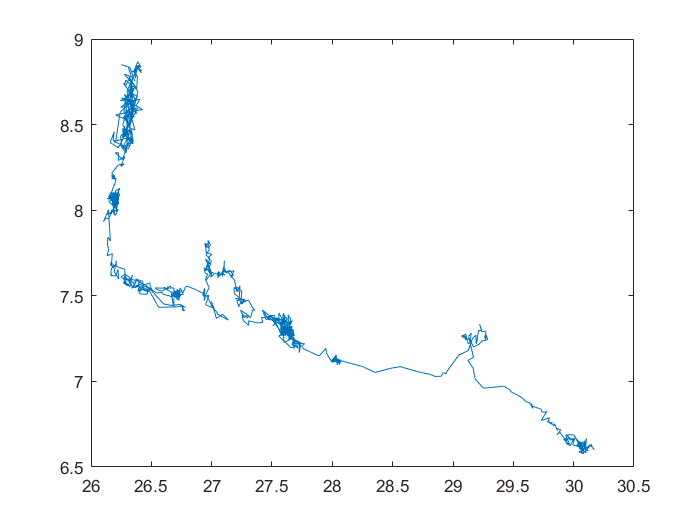

id = 786;
mat = pd.getRawMatById(id,[2:3]);
plot(mat(:,1),mat(:,2));

## try param

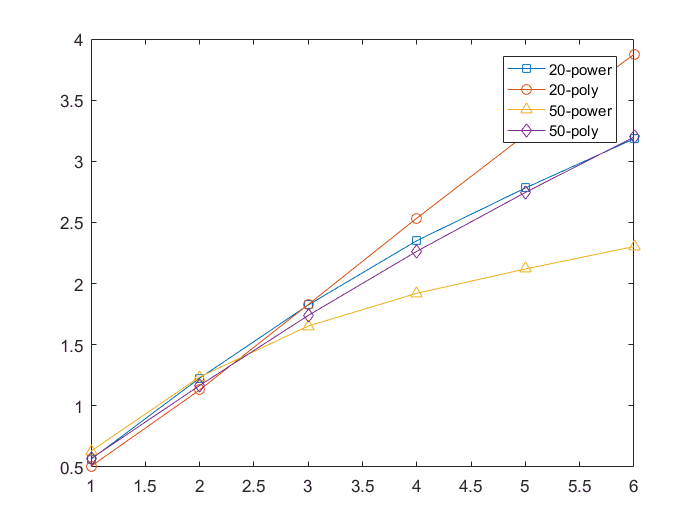

lag = [20,50];
maxP = 6;
curve1 = zeros(maxP,lag(1));
curve2 = zeros(maxP,lag(2));
for m = 1:1:maxP
    curve1(m,:) = TrajAnalysis2D.xy2msd(mat,lag(1),m);
    curve2(m,:) = TrajAnalysis2D.xy2msd(mat,lag(2),m);
end
res = zeros(4,maxP);
for m = 1:1:maxP
    fobject = fit((1:1:lag(1))',curve1(m,:)','power1');
    res(1,m) = fobject.b;
    fobject = fit(log(1:1:lag(1))',log(curve1(m,:))','poly1');
    res(2,m) = fobject.p1;
    fobject = fit((1:1:lag(2))',curve2(m,:)','power1');
    res(3,m) = fobject.b;
    fobject = fit(log(1:1:lag(2))',log(curve2(m,:))','poly1');
    res(4,m) = fobject.p1;
end

figure;
plot(1:1:maxP,res(1,:),'Marker','s','DisplayName','20-power');
hold on;
plot(1:1:maxP,res(2,:),'Marker','o','DisplayName','20-poly');
plot(1:1:maxP,res(3,:),'Marker','^','DisplayName','50-power');
plot(1:1:maxP,res(4,:),'Marker','d','DisplayName','50-poly');
legend show